# Derivation of the **PASSIVE** rotation matrix

## Start with a clean slate

Clear any workspace varables

clc;  clear

## The Angular orientation of the wheel

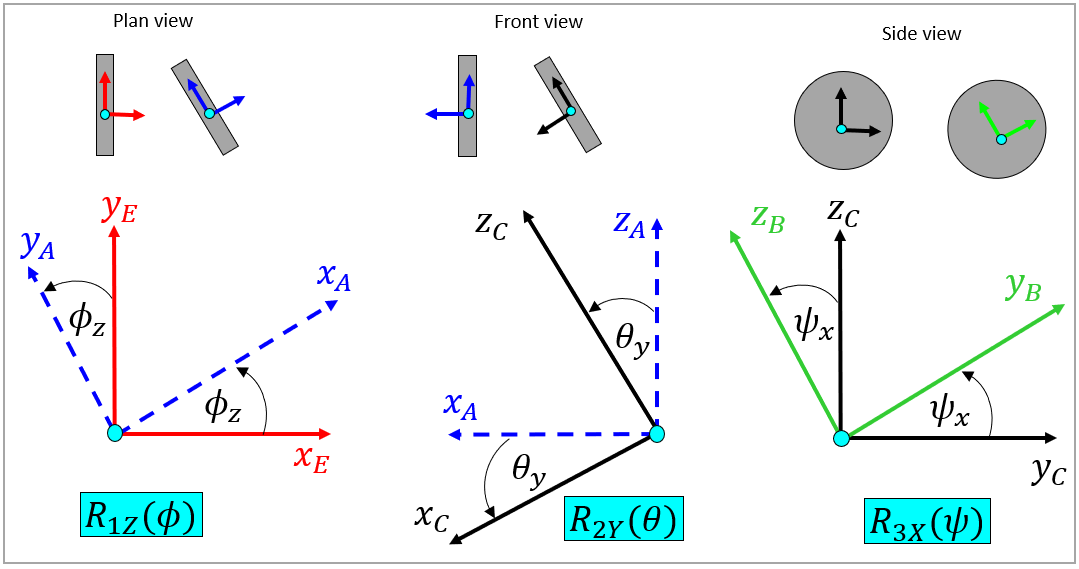  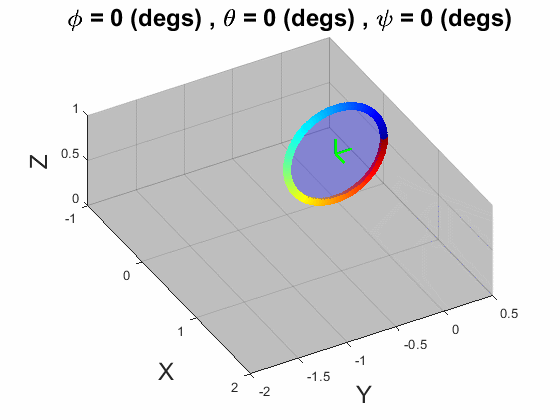

Let's use 3 **Euler angles **to describe the wheel's angular orientation.  

- $R_{1Z}$ occurs 1st about the LOCAL **Z** body axis $(\phi)$, aka **YAW**

- $R_{2Y}$ occurs 2nd about the LOCAL **Y** body axis $(\theta)$, aka **PITCH**

- $R_{3X}$ occurs 3rd about the LOCAL **X** body axis $(\psi)$, aka **ROLL**

We can then express a vector defined in terms of the **Inertial {E-frame}** components , to it's corresponding components in a **body fixed {B-frame}**, using a sequence of **PASSIVE** rotation matrices, ie:

- 
$$\begin{array}{l}
v^B \;=\;\;\left\lbrack R_{3X} \left(\psi \right)\right\rbrack \;\ldotp \left\lbrack R_{2Y} \left(\theta \right)\right\rbrack \;\ldotp \left\lbrack R_{1Z} \left(\phi \right)\right\rbrack \;\ldotp \;\;v^E \;\\
\;\;\;\;\;\;\;={\;R}_{\mathrm{BE}} \;\ldotp v_E 
\end{array}$$


syms psi   theta   phi

R_BE =  LOC_get_RX(psi) * LOC_get_RY(theta) * LOC_get_RZ(phi)

$$R\_BE = \left(\begin{array}{ccc} \cos\left(\varphi \right)\,\cos\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & -\sin\left(\theta \right)\\ \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right)\\ \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}\right)$$

# Local Subfunctions only beyond this point

Hello 

Define the passive Rotation matrix - $R_X \;\;\;\textrm{where}\;\;\;\;{}^Bv=\;\left\lbrack R_X \left(a\right)\right\rbrack \;\ldotp \;{}^Gv$

function R = LOC_get_RX(a)

    OBJ = bh_rot_passive_G2B_CLS({'D1X'}, a, 'SYM');
    R   = OBJ.get_R;
end

Define the passive Rotation matrix - $R_Y \;\;\;\textrm{where}\;\;\;\;{}^Bv=\;\left\lbrack R_Y \left(a\right)\right\rbrack \;\ldotp \;{}^Gv$

function R = LOC_get_RY(a)

    OBJ = bh_rot_passive_G2B_CLS({'D1Y'}, a, 'SYM');
    R   = OBJ.get_R;
end

Define the passive Rotation matrix - $R_Z \;\;\;\textrm{where}\;\;\;\;{}^Bv=\;\left\lbrack R_Z \left(a\right)\right\rbrack \;\ldotp \;{}^Gv$

function R = LOC_get_RZ(a)

    OBJ = bh_rot_passive_G2B_CLS({'D1Z'}, a, 'SYM');
    R   = OBJ.get_R;
end